## Q2) Network Modelling

Q2) a) i) Getting a nxn street network

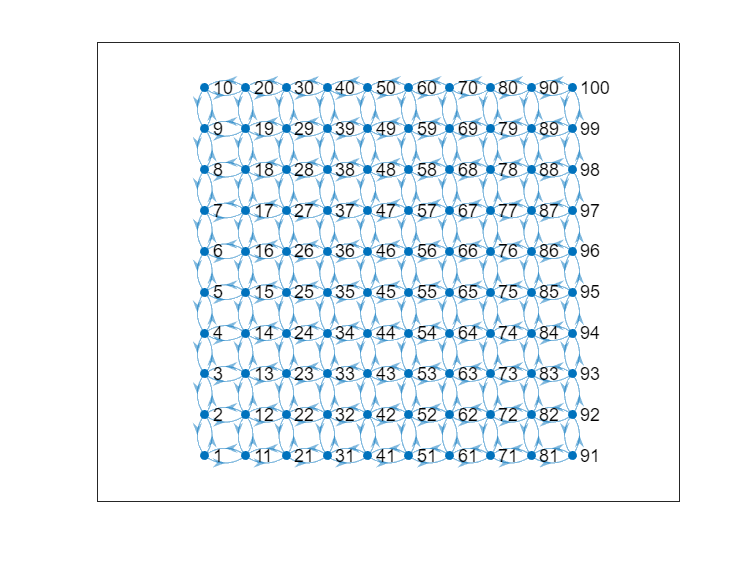

close all
clear

n = 10; % the number of nodes in each direction - experiment with this
L = 0.1; % the grid "pitch" in kilometres (for example)
A = -L*delsq(numgrid('S',n+2));

% manipulating grid
G = digraph(A,'omitselfloops');

num_edges = height(G.Edges);
num_nodes = height(G.Nodes);

rng('default')

G.Nodes.PosX = L*floor((0:n^2-1)/n)';
G.Nodes.PosY = L*rem((0:n^2-1), n)';

% add weights corresponding to distance
function dis_w = distweights(s_x, s_y, t_x, t_y)
    dis_w = sqrt((s_x-t_x)^2+(s_y-t_y)^2);
end

for i = 1:num_edges
    G.Edges.Weight(i) = distweights(G.Nodes.PosX(G.Edges.EndNodes(i,1)), G.Nodes.PosY(G.Edges.EndNodes(i,1)), G.Nodes.PosX(G.Edges.EndNodes(i,2)), G.Nodes.PosY(G.Edges.EndNodes(i,2)));
end

h = plot(G);
h.XData = G.Nodes.PosX;
h.YData = G.Nodes.PosY;
% title("Graph with Junction Nodes")
axis equal

Q2) b) Modelling morning commute of residents from all nodes origin to 1 of 4 corners

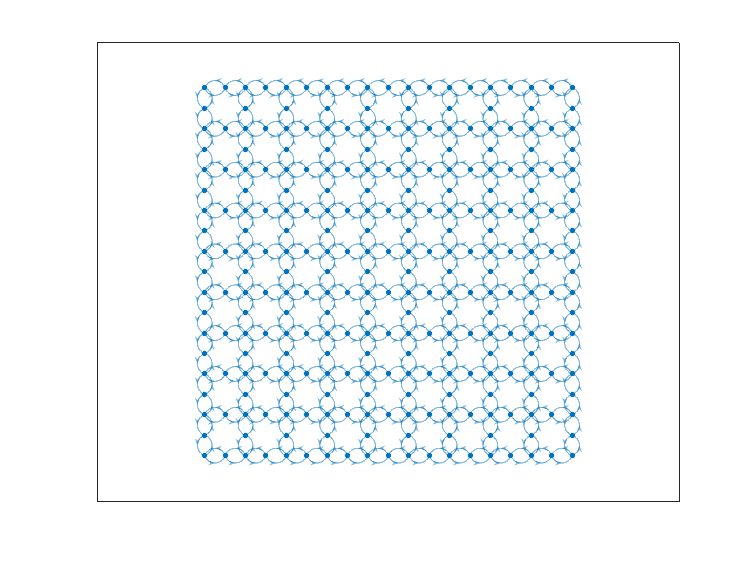

% generating street origin matrix
% nodes in the middle of each edge of orginal graph
B = G;

% remove all old edges
% Get all edges
allEdges = B.Edges.EndNodes;

% Remove all edges
B = rmedge(B, allEdges(:,1), allEdges(:,2));

% shift originals right
rd_length = G.Edges.Weight(1,1)/2; % currently grid is uniform
B_rs = G.Nodes.PosX + rd_length;
% remove row
B_rs = B_rs(1:end-n);

% shift orginals up
B_us = G.Nodes.PosY + rd_length;
% remove every tenth element
% Find indices of every nth element
idx_n = n:n:length(B_us);

% Remove the 10th elements
B_us(idx_n) = [];
% B_us = B_us(1:end-10);

% add label to junction nodes
% 1 = junction
% 2 = road
B.Nodes.Type = ones(num_nodes,1);

% add road nodes
B = addnode(B,(2*n^2-2*n));
% right shifted
B.Nodes.PosX(n^2+1:(2*n^2-n)) = B_rs(1:n^2-n);
B.Nodes.PosY(n^2+1:(2*n^2-n)) = B.Nodes.PosY(1:n^2-n);
B.Nodes.Type(n^2+1:(2*n^2-n)) = ones(n^2-n,1)+1;

% up shifted
B.Nodes.PosY((2*n^2-n)+1:(3*n^2-2*n)) = B_us(1:n^2-n);
% getting rid of every nth element
B_x = B.Nodes.PosX(1:n^2);
B_x(idx_n) = [];
B.Nodes.PosX((2*n^2-n)+1:(3*n^2-2*n)) = B_x;
B.Nodes.Type((2*n^2-n)+1:(3*n^2-2*n)) = ones(n^2-n,1)+1;

% add edges with adjacent nodes
% 2 edges per road node
% each right shifted node (101 - 190) connects
s_arr = repmat(n^2+1:(3*n^2-2*n), 2, 1);  % Repeat each number twice
s_arr = s_arr(:)'; % reshaped into row vector
s_arr = s_arr';

% targets are start and end of the original edges
% for all the right shifted roads (every even edge)
rs_idx = 2:2:num_edges;
us_idx = 1:2:num_edges;
t_arr = zeros(length(s_arr),1);
% first half is right shifted nodes
for i = 0:length(s_arr)/4-1
    t_arr(2*i+1) = i + 1;
    t_arr(2*i+2) = i + n + 1;
end
% second half is up shifted nodes
offset = length(s_arr)/2;

t_us = 1:n^2;
t_us(idx_n) = [];

for i = 0:length(s_arr)/4-1
    t_arr(offset + (2*i+1)) = t_us(i+1);
    t_arr(offset + (2*i+2)) = t_us(i+1)+1;
end

B = addedge(B, s_arr, t_arr, rd_length.*ones(1,length(s_arr)));
% bi directional
B = addedge(B, t_arr, s_arr, rd_length.*ones(1,length(s_arr)));
h = plot(B);
h.XData = B.Nodes.PosX;
h.YData = B.Nodes.PosY;
% title("Graph with Road Nodes")

% add colour coded plotting
axis equal

num_nodes = height(B.Nodes);
num_edges = height(B.Edges);

% destination nodes
d_nodes = [1 n n^2-n+1 n^2];
% get indices for road nodes
idx_rd = find(B.Nodes.Type==2);


% categorise_graph
G_2 = categorise_roads(B, h, n);

## Base Model

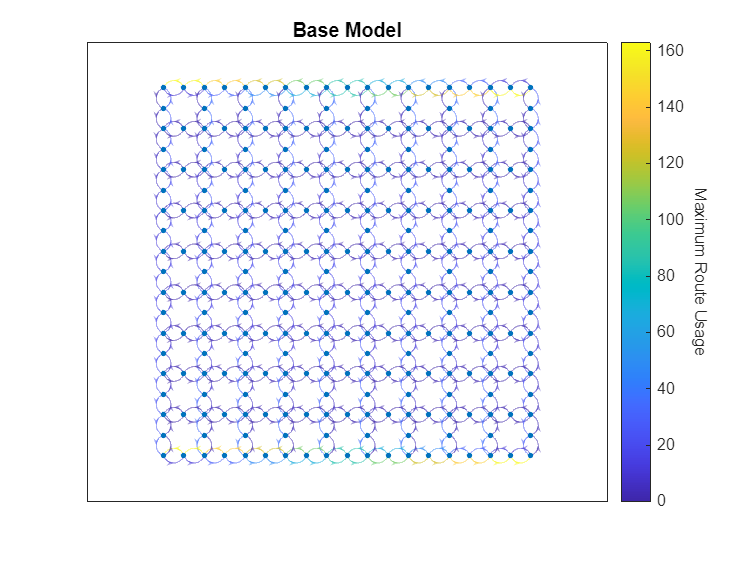

% getting base results for no LTNs
% can functionalise this as will be doing this hotness plot for every
% scenario

% get shortest path between origin and destination for all journies
% We're assuming that everyone takes the shortest route available

route_use(G_2,idx_rd,d_nodes, "Base Model");


%% can see that a lot of the traffic goes along the outer most roads

## Supergrid LTNs

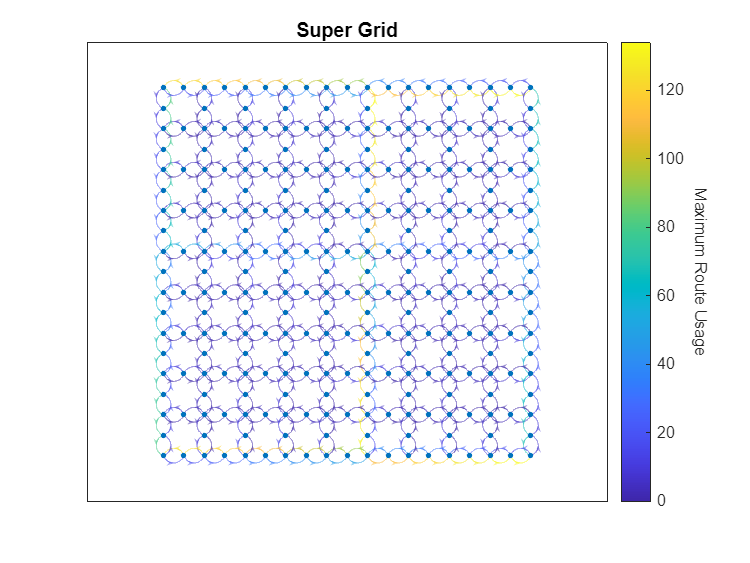

SG_base = G_2;

% Assign smaller weights to ring roads
% find ring road edge indices
rr_idx = find(SG_base.Edges.rd_idx==0 | SG_base.Edges.rd_idx==9);
SG_base.Edges.Weight(rr_idx) = 0.025; % half the weighting

% find cross road edge indices

xrd_idx = find(SG_base.Edges.rd_idx== round(n/2));
SG_base.Edges.Weight(xrd_idx) = 0.025; % half the weighting

route_use(SG_base,idx_rd,d_nodes, "Super Grid");


%% can see that a lot of the traffic goes along the outer most roads

## Supergrid with one way traffic

SG_1w = G_2;
% assign ring road and cross road weights
SG_1w.Edges.Weight(rr_idx) = 0.025;
SG_1w.Edges.Weight(xrd_idx) = 0.025;

% make all other streets one way (+ve direction)
neg_dir_idx = find(SG_1w.Edges.Dir == 2 & SG_1w.Edges.rd_idx ~= 0 & SG_1w.Edges.rd_idx ~= 9 & SG_1w.Edges.rd_idx ~= round(n/2));
SG_1w = rmedge(SG_1w,neg_dir_idx);

connectivity_check(SG_1w,idx_rd,d_nodes)

Can travel from all street nodes to all corner nodes: true
Can travel from all corner nodes to all street nodes: true


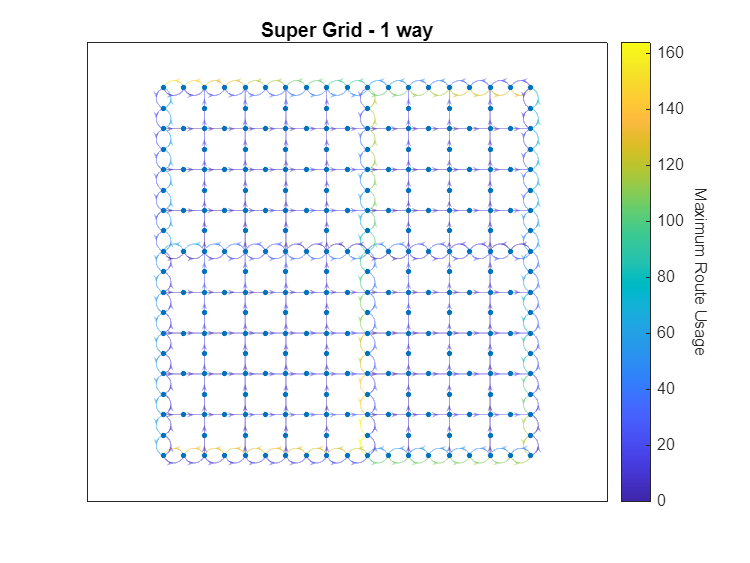


route_use(SG_1w,idx_rd,d_nodes, "Super Grid - 1 way");

## Supergrid with dead ends

% assigning in degree and out degree
SG_de = SG_base;
in_deg = indegree(SG_de);
out_deg = outdegree(SG_de);
SG_de.Nodes.in_deg = in_deg;
SG_de.Nodes.out_deg = out_deg;

% find all nodes with degree of 4
four_deg_node = find(SG_de.Nodes.in_deg==4);
% find all edges that have join to these nodes
[~, four_deg_e_logarr_1] = ismember(SG_de.Edges.EndNodes(:,1),four_deg_node);
[~, four_deg_e_logarr_2] = ismember(SG_de.Edges.EndNodes(:,2),four_deg_node);
four_deg_e_logarr = four_deg_e_logarr_1 + four_deg_e_logarr_2;

four_deg_edge = find(four_deg_e_logarr>0);

% randomly select num_dead to remove from the graph
rng(16)
num_dead = 10; % model 10 dead ends
dead_sel_idx = randi(length(four_deg_edge),num_dead,1);

dead_sel_idx_2 = zeros(num_dead,1);

% find index of opposite edge and append
for i = 1:num_dead
    opp_dead_idx = find((SG_de.Edges.EndNodes(:,1) == SG_de.Edges.EndNodes(dead_sel_idx(i),2)) & (SG_de.Edges.EndNodes(:,2) == SG_de.Edges.EndNodes(dead_sel_idx(i),1)));
    dead_sel_idx_2(i) = opp_dead_idx;
end

% append these indexes
dead_sel = [dead_sel_idx; dead_sel_idx_2];

% remove these edges to make deadends
SG_de = rmedge(SG_de,dead_sel);

connectivity_check(SG_de,idx_rd,d_nodes)

Can travel from all street nodes to all corner nodes: true
Can travel from all corner nodes to all street nodes: true


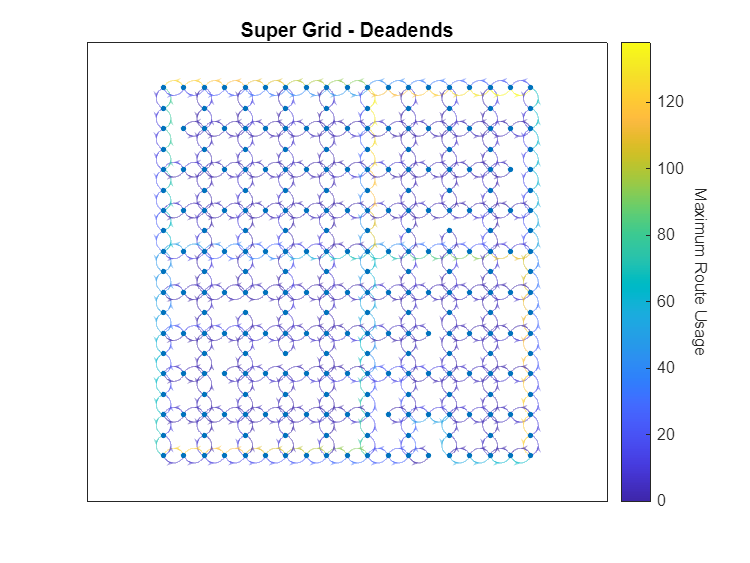

route_use(SG_de,idx_rd,d_nodes, "Super Grid - Deadends");